# Analyzing Bike Motion: 

## Bike Linear Acceleration: 

- Collecting data and organizing it into different variable

%name of file in the same folder 
%load data
name = "60_stat_clipped.mat";
s = load(name)

s = struct with fields:
    x60_stationary: [19703×5 double]


c = struct2cell(s);
frequency_data = [c{:}];
%Clipped
frequency_data = frequency_data(1:19000, :);
time = frequency_data(:,1); 
x = frequency_data(:,2);
y = frequency_data(:,3);
z = frequency_data(:,4);

X_max_acceleration = max(x);
Y_max_acceleration = max(y);
Z_max_acceleration = max(z);
X_min_acceleration = min(x);
Y_min_acceleration = min(y);
Z_min_acceleration = min(z);


Based on our motion model, Z is up and down, Y is left to right, and X is out of the Pedal. Based on the motion of biking, we would assume Z has the greatest magnitude then Y. With X having a small movment since the bike pedal ideally does not have a degree of freedom in X axis. 

The following tests checks out theory. 

if (Z_max_acceleration > Y_max_acceleration) > X_max_acceleration
    disp("True, Z>Y>Z")
end 

True, Z>Y>Z


% Make and Save Linear Acceleration v. Time graphs

The graphs should also show the same statment.

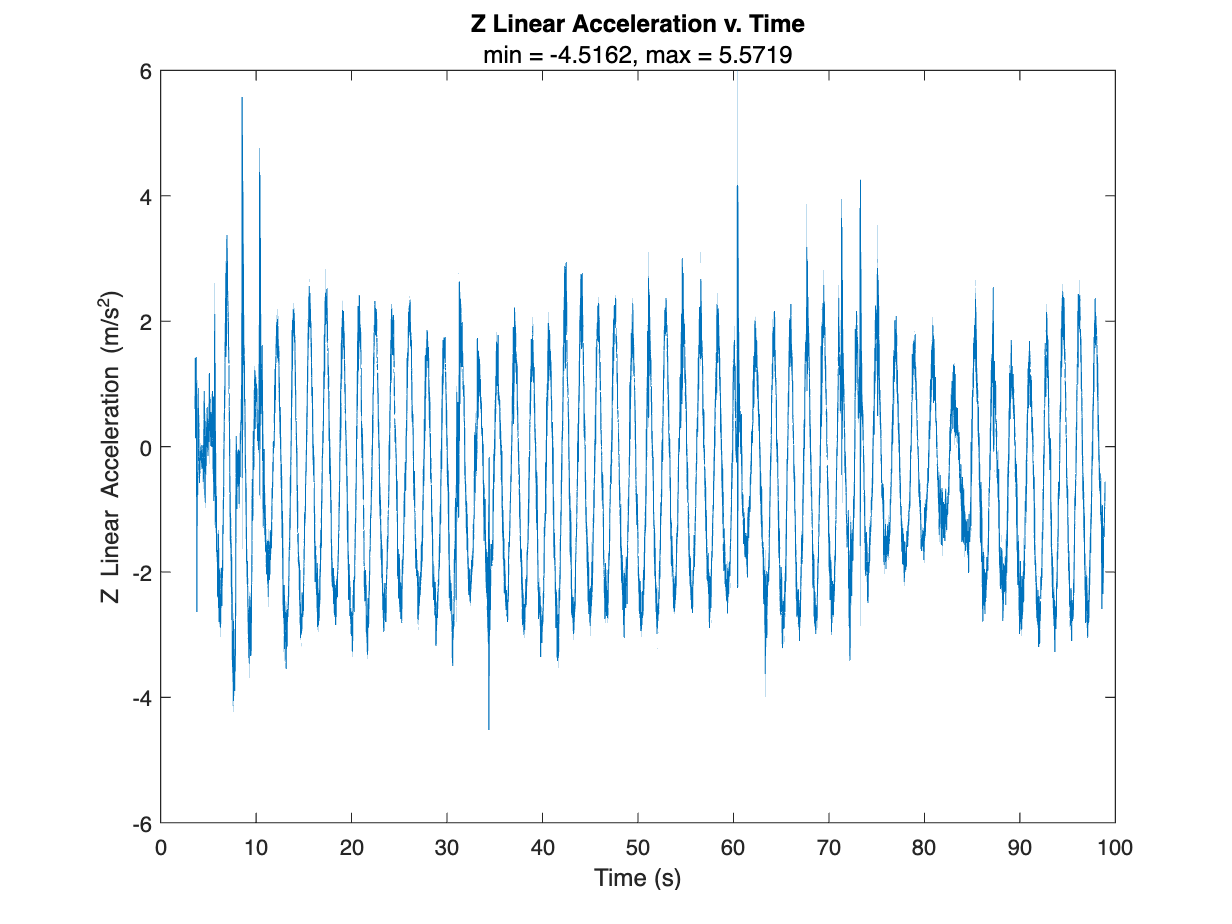

%Z graph
plot(time,z)
title("Z Linear Acceleration v. Time")
subtitle("min = " + Z_min_acceleration + ", max = "+ Z_max_acceleration)
xlabel("Time (s)");
ylabel("Z Linear Acceleration (m/s^2)");

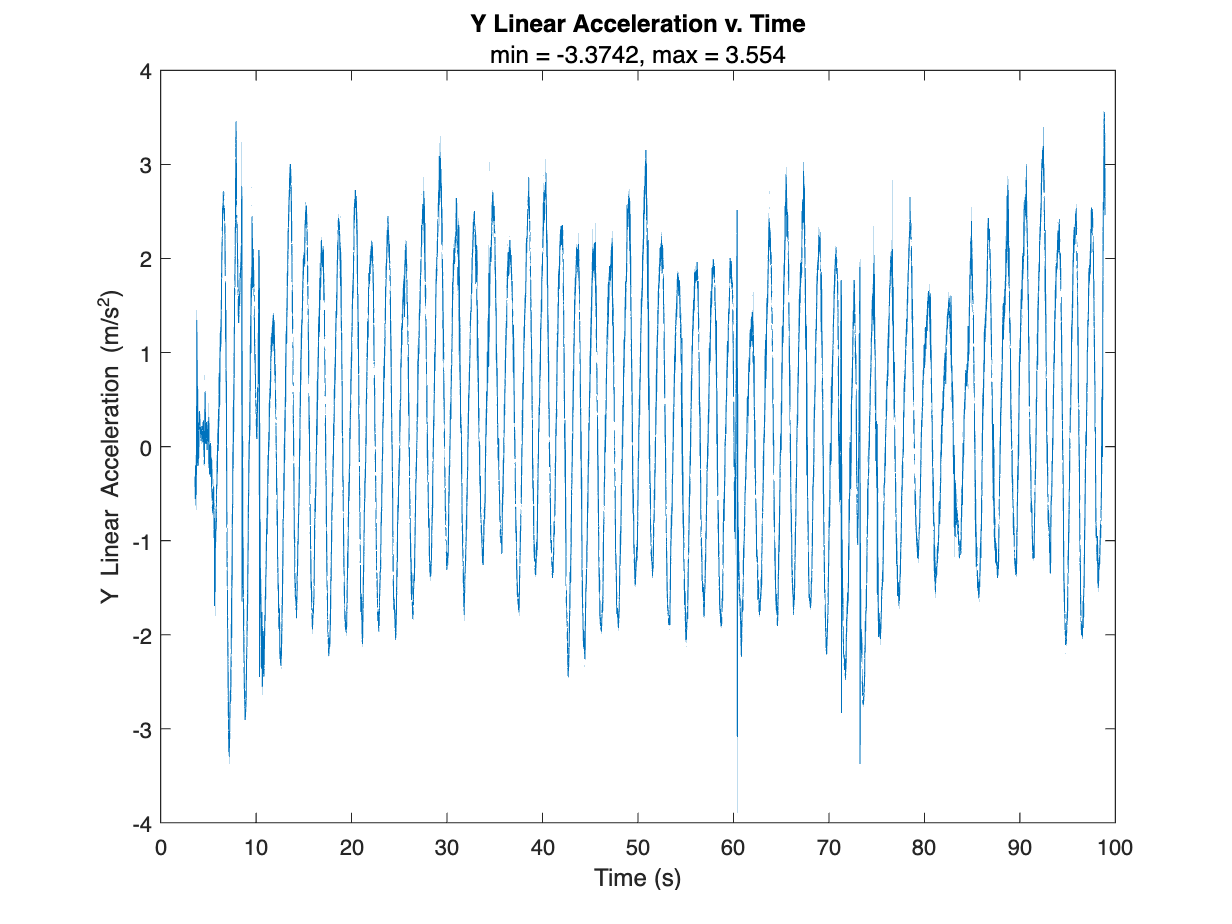

%Y Graph
plot(time,y)
title("Y Linear Acceleration v. Time")
subtitle("min = " + Y_min_acceleration + ", max = "+ Y_max_acceleration)
xlabel("Time (s)");
ylabel("Y Linear Acceleration (m/s^2)");

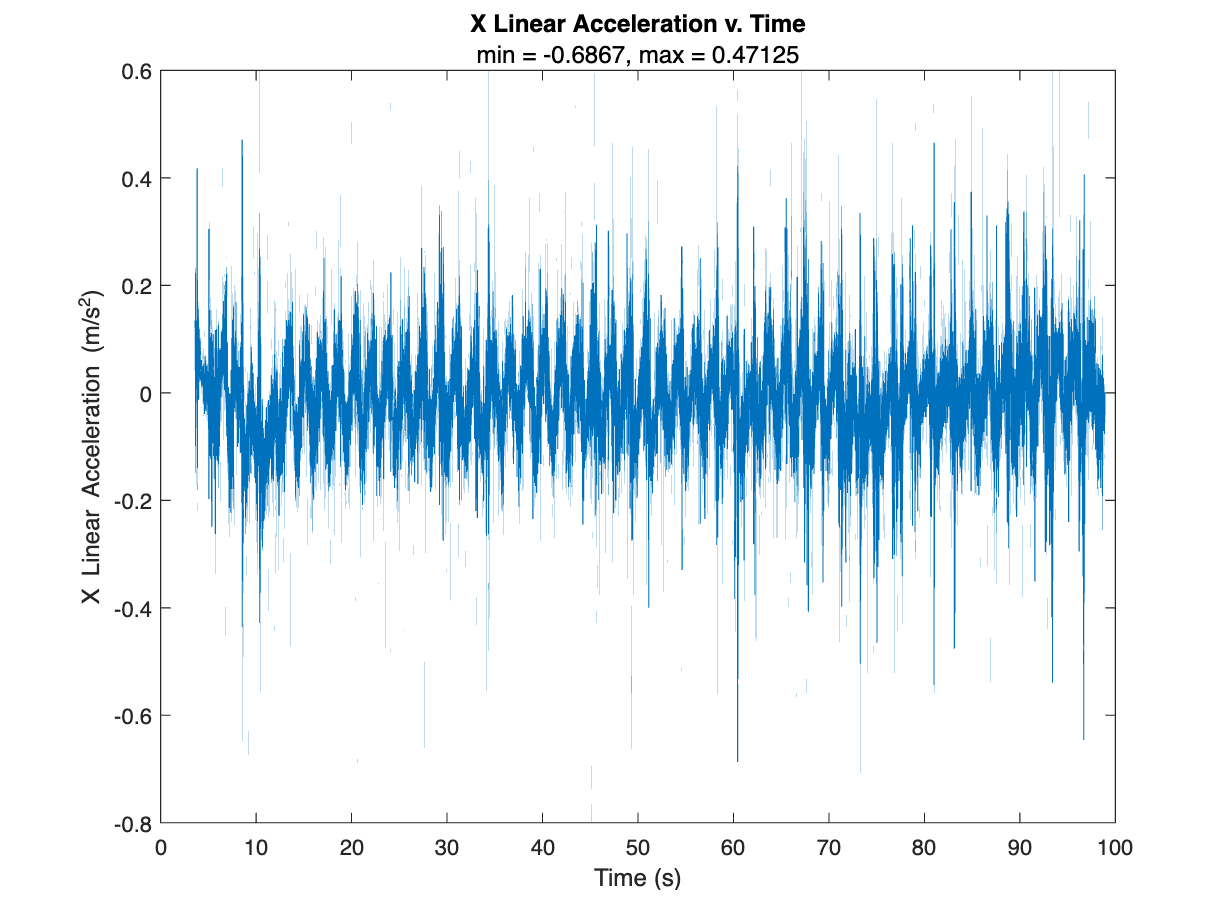

% X Graph
plot(time,x)
title("X Linear Acceleration v. Time")
subtitle("min = " + X_min_acceleration + ", max = "+ X_max_acceleration)
xlabel("Time (s)");
ylabel("X Linear Acceleration (m/s^2)");

In addition, based on the motion model. Z and Y shoudld be offset sinosidal waves. Using a subset of seconds, we can verify this image. 

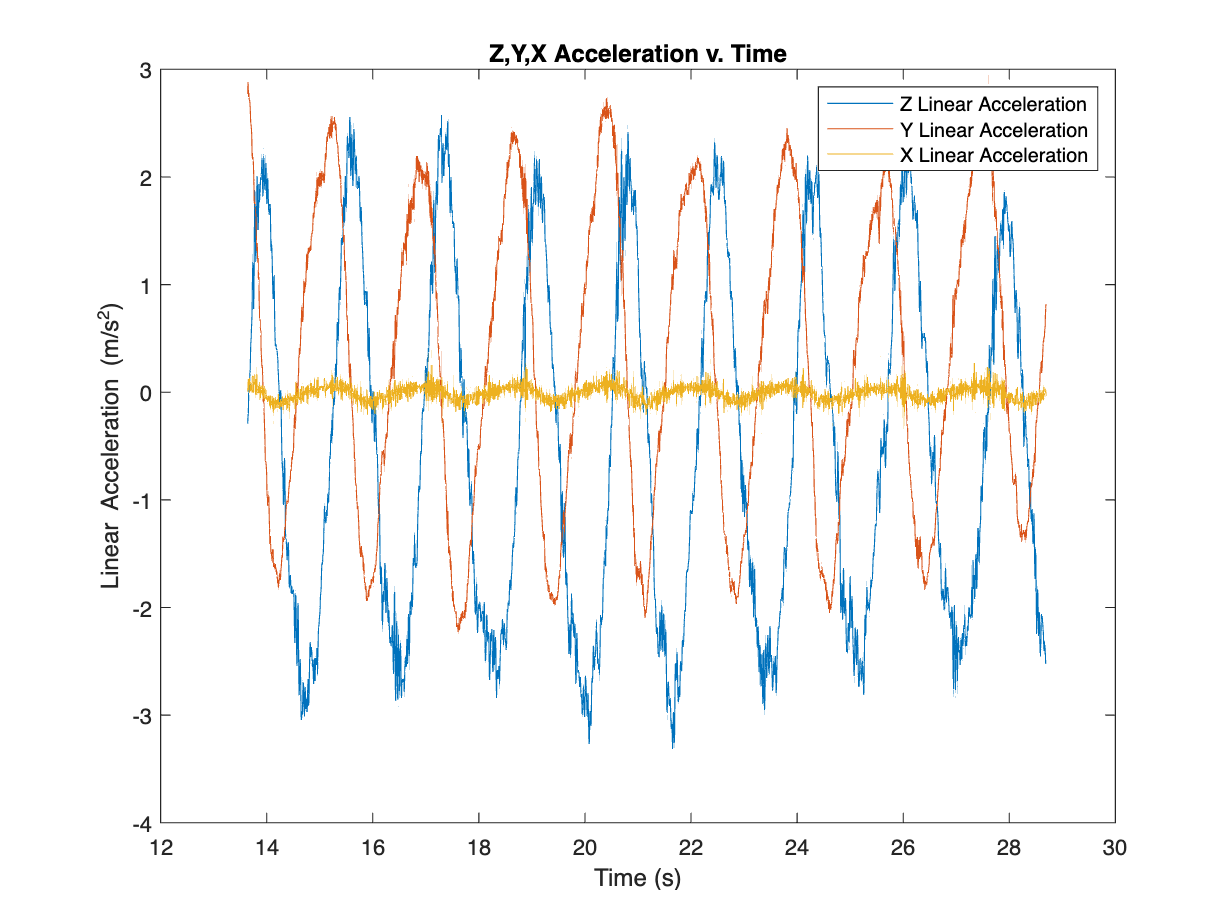

%Graph X and Y
clipped_frequency_data = frequency_data(2000:5000, :);
t_clipped = clipped_frequency_data(:,1);
x_clipped = clipped_frequency_data(:,2);
y_clipped = clipped_frequency_data(:,3);
z_clipped = clipped_frequency_data(:,4);

plot(t_clipped, z_clipped)
hold on
plot(t_clipped, y_clipped)
plot(t_clipped, x_clipped)
ylabel("Linear Acceleration (m/s^2)")
xlabel("Time (s)")
title("Z,Y,X Acceleration v. Time")
legend("Z Linear Acceleration", "Y Linear Acceleration","X Linear Acceleration")
hold off

The graph vervies our motion model. Now that our linear accelration looks liek what we expected, we can move on to makign the frequencies. 

We assume that frequnices of each

bike_freq = []


bike_freq =

     []



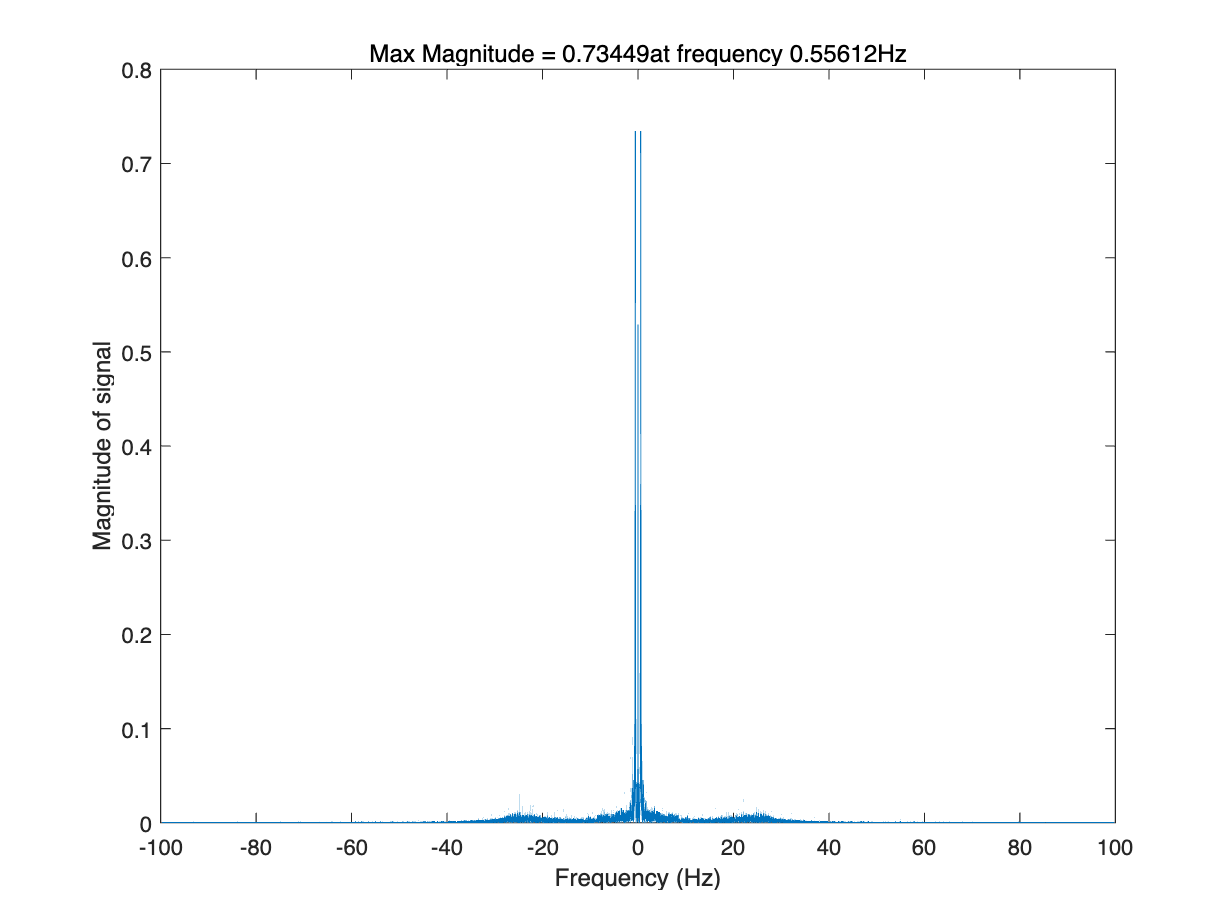

dt = time(2) - time(1);
fs = 1/dt;
% Z Freqency Plot
[fz, mz] = make_freq_plot(z,fs);

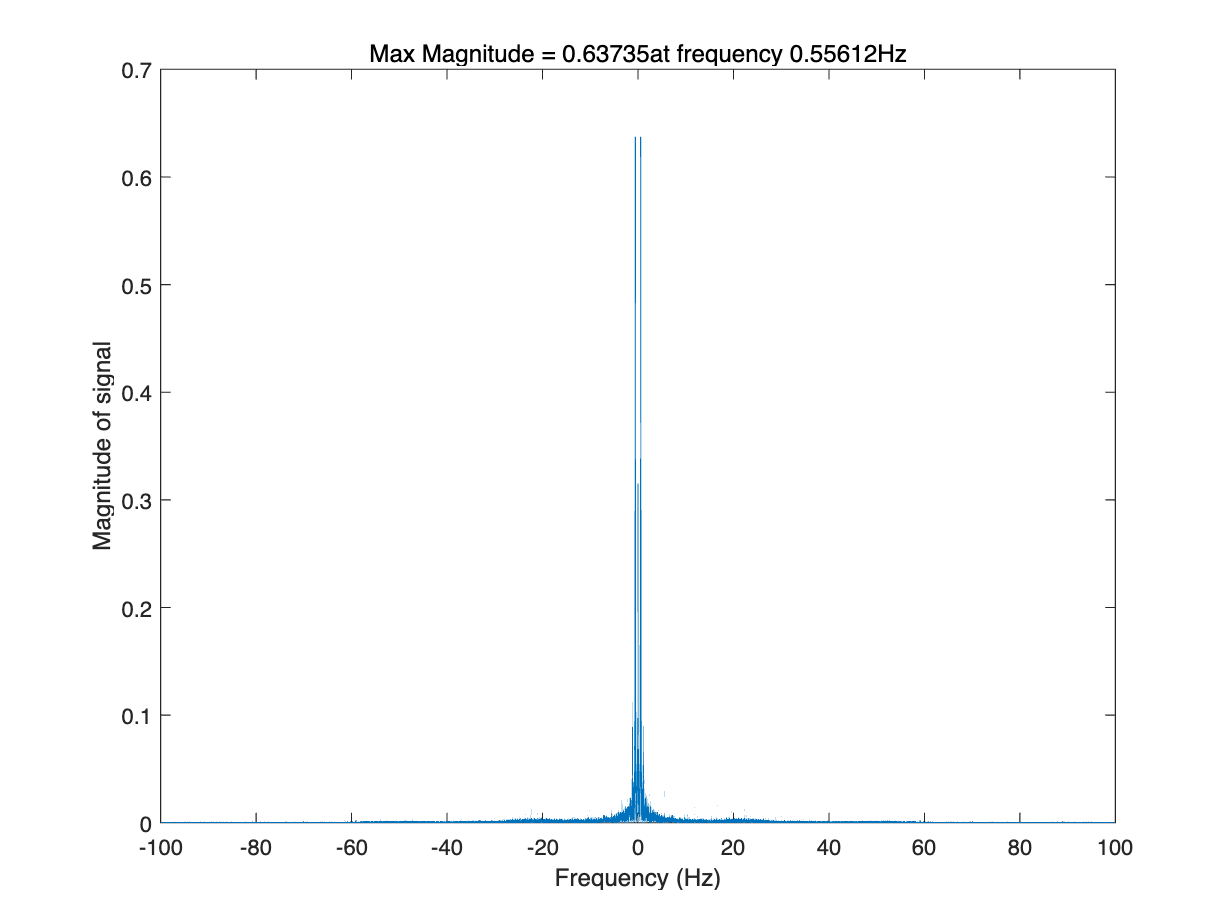

bike_freq(1) = fz;

% Y Freqency Plot
[my, fy] = make_freq_plot(y,fs);

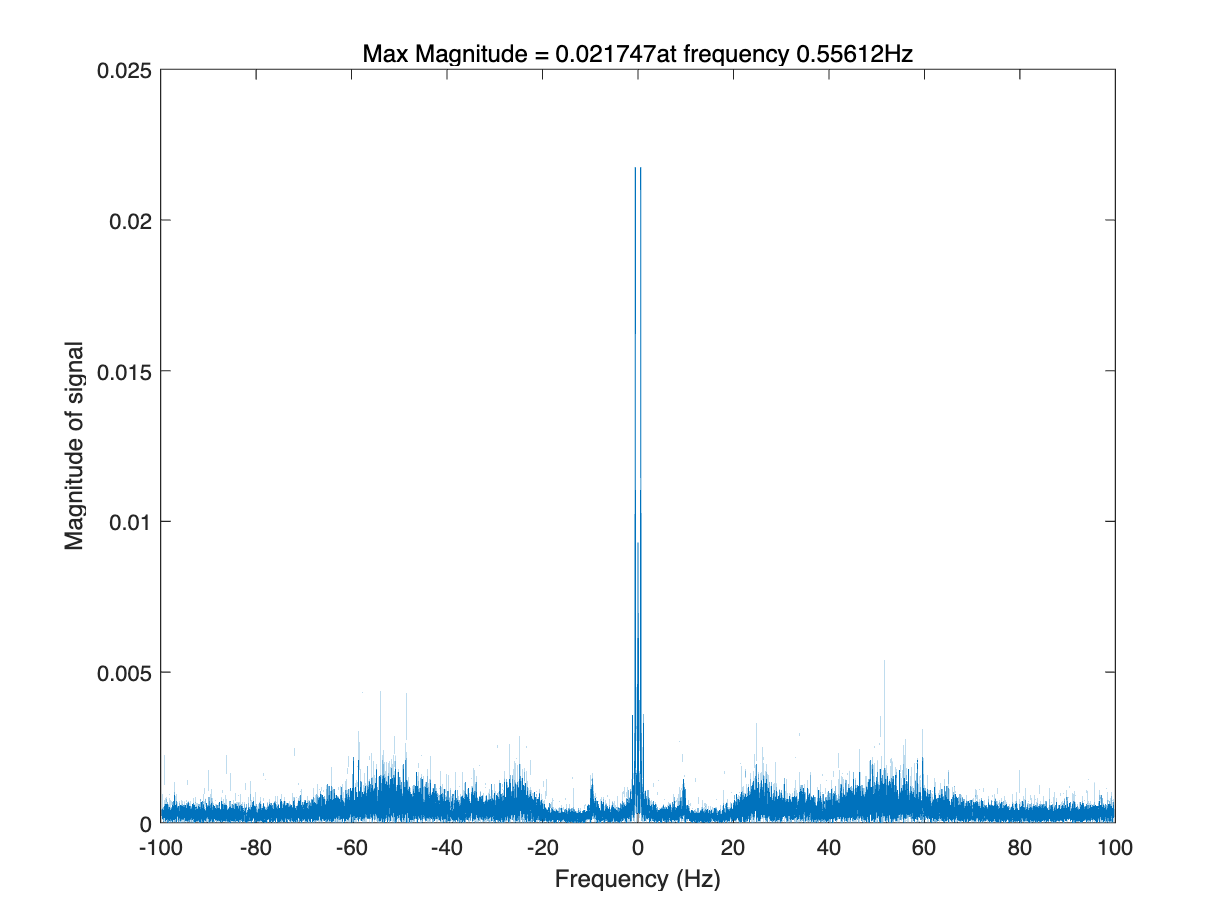

bike_freq(2) = fy;
% X freqency plot
[mx, fx] = make_freq_plot(x,fs);

bike_freq(3) = fx;

The bike freqency shoudl be the same in all 3 graphs:

bike_freq

bike_freq =     0.5561    0.6374    0.0217


speed = freq2milage(bike_freq(1), 12)

speed = 2.3824

Our final speed is 2.3824 miles per hour on a stionary bike with each pedal going down to a mentronme of 60